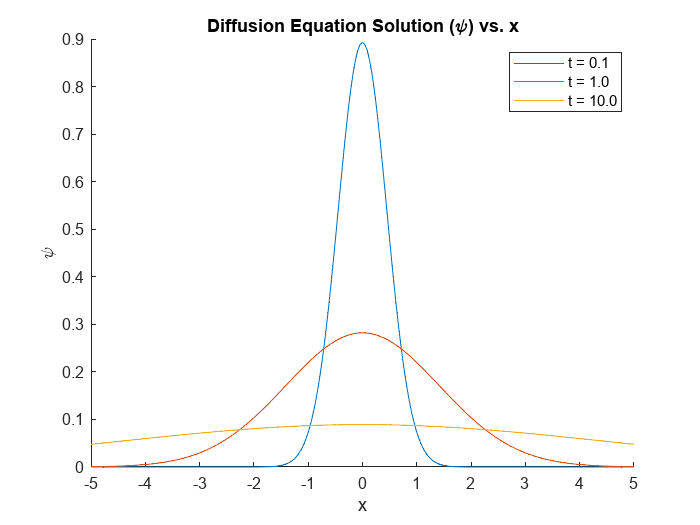

% Define parameters
D = 1;      % Diffusion coefficient
y0 = 1;     % Amplitude of the Gaussian wave pulse
a = 1;      % Parameter in the Gaussian wave pulse
v = 1;      % Wave velocity

% Part A: Plotting ψ versus x for three different values of t
t_values = [0.1, 1, 10]; % Values of t
x = linspace(-5, 5, 1000); % Range for x
figure;
hold on;
for i = 1:length(t_values)
    t = t_values(i);
    psi = (4 * pi * D * t)^(-1/2) * exp(-x.^2 / (4 * D * t));
    plot(x, psi, 'DisplayName', sprintf('t = %.1f', t));
end
title('Diffusion Equation Solution (\psi) vs. x');
xlabel('x');
ylabel('\psi');
legend('Location', 'best');
hold off;

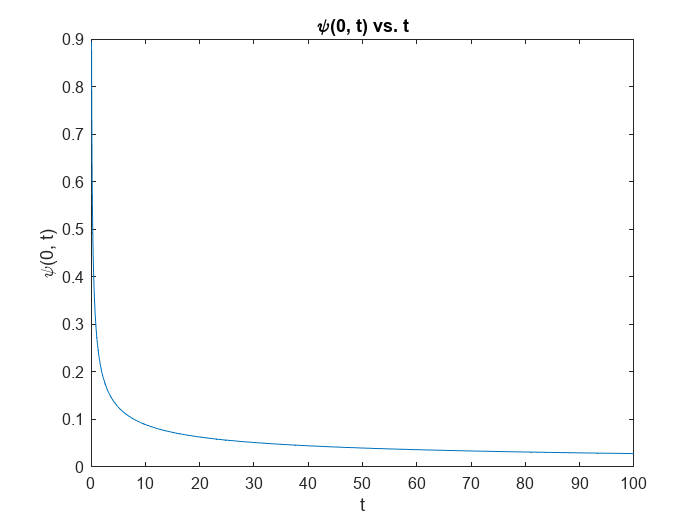


% Part B: Plotting ψ(0, t) versus t
t_values = logspace(-1, 2, 100); % Values of t in log space
psi_0 = (4 * pi * D * t_values).^(-1/2); % Value of ψ at x=0
figure;

plot(t_values, psi_0, '-');
title('\psi(0, t) vs. t');
xlabel('t');
ylabel('\psi(0, t)');

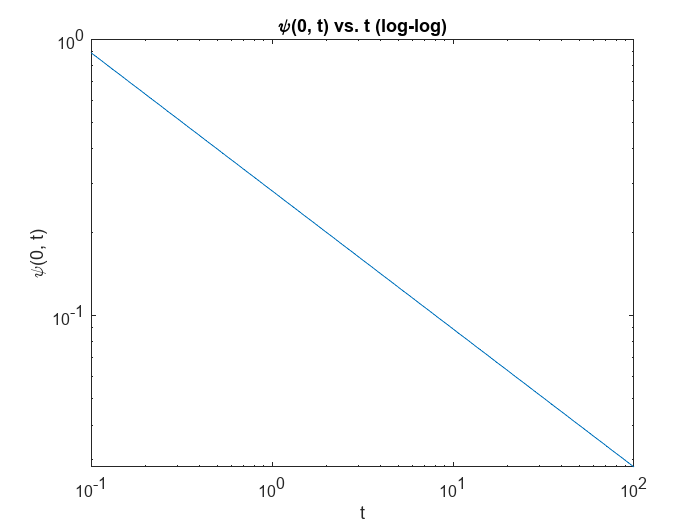

figure;
loglog(t_values, psi_0, '-');
title('\psi(0, t) vs. t (log-log)');
xlabel('t');
ylabel('\psi(0, t)');

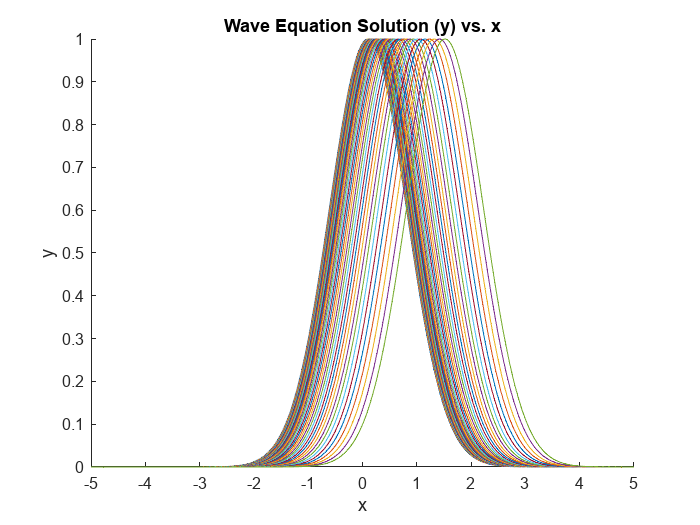


% Part C: Plotting y versus x for the same three values of t
figure;
hold on;
for i = 1:40
    t = t_values(i);
    y = y0 * exp(-a * (x - v * t).^2);
    plot(x, y, 'DisplayName', sprintf('t = %.1f', t));
end
title('Wave Equation Solution (y) vs. x');
xlabel('x');
ylabel('y');
%legend('Location', 'best');
hold off;


% Part D: Conclusions
disp('Conclusions:');

Conclusions:


disp('1. As time increases, the diffusion solution spreads out, covering a larger area around the origin.');

1. As time increases, the diffusion solution spreads out, covering a larger area around the origin.


disp('2. The value of ψ at the origin (ψ(0, t)) decreases with increasing time, demonstrating diffusion.');

2. The value of ψ at the origin (ψ(0, t)) decreases with increasing time, demonstrating diffusion.


disp('3. The Gaussian wave pulse solution simulates a traveling wave, shifting its profile as time progresses.');

3. The Gaussian wave pulse solution simulates a traveling wave, shifting its profile as time progresses.
